# 多尺度卷积神经网络

## 清空环境和图窗

clear
close all

## 实验环境（硬件和软件）

% win10 Desktop
computer

ans = 'PCWIN64'

% GPU
gpuDevice

ans =   CUDADevice - 属性:

                      Name: 'NVIDIA GeForce RTX 3060'
                     Index: 1
         ComputeCapability: '8.6'
            SupportsDouble: 1
             DriverVersion: 11.8000
            ToolkitVersion: 11.2000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152 (49.15 KB)
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 12884246528 (12.88 GB)
           AvailableMemory: 10434290560 (10.43 GB)
       MultiprocessorCount: 28
              ClockRateKHz: 1837000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


## 准备数据集

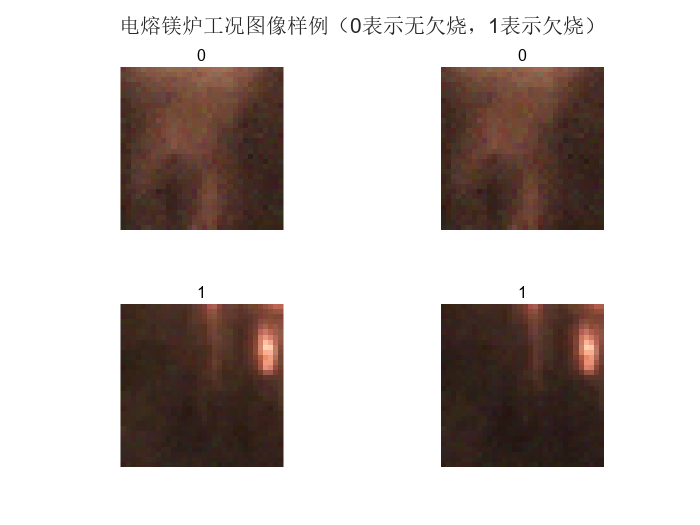

% 训练集
trainlabels = [];
trainImgs = [];
filedir = dir("C:\Users\Administrator\Documents\MATLAB\SAPI-FMF\SAPI-FMF 数据集\训练集\traindata*.mat");
for i = 1:length(filedir)
    fileName{i} = fullfile(filedir(i).folder,filedir(i).name);
    temp = importdata(fileName{i});
    trainImgs = cat(4,trainImgs,temp.video);
    trainlabels = [trainlabels,temp.label];
end
trainlabels = categorical(trainlabels');

% 训练集可视化
t1 = tiledlayout(2,2);
for i = 19025:19028
    nexttile
    imshow(trainImgs(:,:,:,i));
    title(trainlabels(i));
end
title(t1,'电熔镁炉工况图像样例（0表示无欠烧，1表示欠烧）')

% 验证集
vallabels = [];
valImgs = [];
filedir = dir("C:\Users\Administrator\Documents\MATLAB\SAPI-FMF\SAPI-FMF 数据集\验证集\testdata*.mat");
for i = 1:length(filedir)
    fileName{i} = fullfile(filedir(i).folder,filedir(i).name);
    temp = importdata(fileName{i});
    valImgs = cat(4,valImgs,temp.video);
    vallabels = [vallabels,temp.label];
end
vallabels = categorical(vallabels');

%

## 定义网络

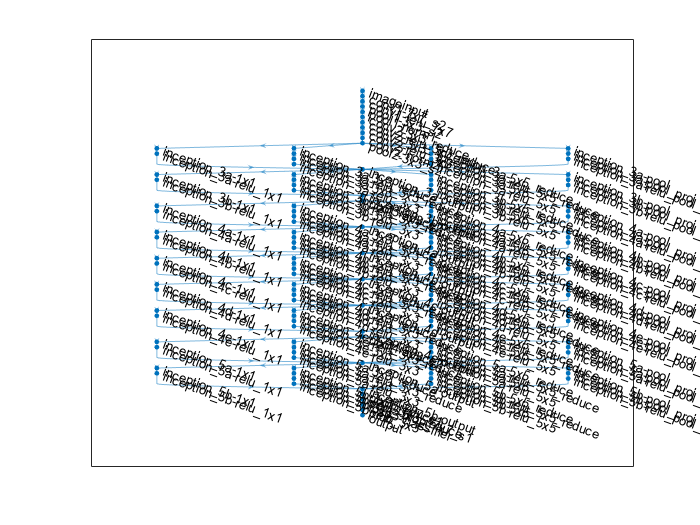

lgraph = layerGraph();
tempLayers = [
    imageInputLayer([32 32 3],"Name","imageinput")
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2])
    reluLayer("Name","conv1-relu_7x7")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","conv2-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","conv2-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","conv2-relu_3x3")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_3x3_reduce")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_5x5_reduce")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_3b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_5x5_reduce")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_3b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_3b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_3x3_reduce")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_5x5_reduce")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_3x3_reduce")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_3x3_reduce")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4c-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4c-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4c-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_3x3_reduce")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4d-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4d-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4d-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_4e-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_4e-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_4e-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_3x3_reduce")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","inception_5b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","inception_5b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj","BiasLearnRateFactor",2)
    reluLayer("Name","inception_5b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1")
    dropoutLayer(0.4,"Name","pool5-drop_7x7_s1")
    fullyConnectedLayer(2,"Name","loss3-classifier")
    softmaxLayer("Name","prob")
    classificationLayer("Name","output")];
lgraph = addLayers(lgraph,tempLayers);

% 清理辅助变量
clear tempLayers;

lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-1x1");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-pool");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1","inception_3a-output/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3","inception_3a-output/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5","inception_3a-output/in3");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj","inception_3a-output/in4");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-1x1");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-pool");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1","inception_3b-output/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3","inception_3b-output/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5","inception_3b-output/in3");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj","inception_3b-output/in4");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-1x1");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-pool");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1","inception_4a-output/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3","inception_4a-output/in2");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5","inception_4a-output/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj","inception_4a-output/in4");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-1x1");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-pool");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1","inception_4b-output/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3","inception_4b-output/in2");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5","inception_4b-output/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj","inception_4b-output/in4");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-1x1");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-pool");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1","inception_4c-output/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3","inception_4c-output/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5","inception_4c-output/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj","inception_4c-output/in4");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-1x1");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-pool");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1","inception_4d-output/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3","inception_4d-output/in2");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5","inception_4d-output/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj","inception_4d-output/in4");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-1x1");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-pool");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1","inception_4e-output/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3","inception_4e-output/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5","inception_4e-output/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj","inception_4e-output/in4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-1x1");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-pool");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1","inception_5a-output/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3","inception_5a-output/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5","inception_5a-output/in3");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj","inception_5a-output/in4");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-1x1");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-pool");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1","inception_5b-output/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3","inception_5b-output/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5","inception_5b-output/in3");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj","inception_5b-output/in4");

figure
plot(lgraph)

lgraph.Layers

ans =   具有以下层的 144×1 Layer 数组:

     1   'imageinput'                     图像输入         32×32×3 图像: 'zerocenter' 归一化
     2   'conv1-7x7_s2'                   二维卷积         64 7×7 卷积: 步幅 [2  2]，填充 [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU            ReLU
     4   'pool1-3x3_s2'                   二维最大池化      3×3 最大池化: 步幅 [2  2]，填充 [0  1  0  1]
     5   'pool1-norm1'                    跨通道归一化      跨通道归一化: 每元素 5 个通道
     6   'conv2-3x3_reduce'               二维卷积         64 1×1 卷积: 步幅 [1  1]，填充 [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU            ReLU
     8   'conv2-3x3'                      二维卷积         192 3×3 卷积: 步幅 [1  1]，填充 [1  1  1  1]
     9   'conv2-relu_3x3'                 ReLU            ReLU
    10   'conv2-norm2'                    跨通道归一化      跨通道归一化: 每元素 5 个通道
    11   'pool2-3x3_s2'                   二维最大池化      3×3 最大池化: 步幅 [2  2]，填充 [0  1  0  1]
    12   'incepti

## 训练网络

正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　３０．４７％　｜　　５９．２４％　｜　　０．６９３５　｜　０．６９３０　｜　　０．００１０　｜
｜　　　１　｜　　　５０　｜　　　　　００：００：０５　｜　　　７５．７８％　｜　　　　　　　　　｜　　０．５８９０　｜　　　　　　　　｜　　０．００１０　｜
｜　　　１　｜　　１００　｜　　　　　００：００：０８　｜　　　７８．１２％　｜　　４６．２８％　｜　　０．５３４５　｜　０．８３９９　｜　　０．００１０　｜
｜　　　１　｜　　１５０　｜　　　　　００：００：１１　｜　　　８２．８１％　｜　　　　　　　　　｜　　０．４７３９　｜　　　　　　　　｜　　０．００１０　｜
｜　　　２　｜　　２００　｜　　　　　００：００：１５　｜　　　７７．３４％　｜　　４６．２８％　｜　　０．５３３１　｜　０．９０８２　｜　　０．００１０　｜
｜　　　２　｜　　２５０　｜　　　　　００：００：１８　｜　　　７１．０９％　｜　　　　　　　　　｜　　０．６０９２　｜　　　　　　　　｜　　０．００１０　｜
｜　　　２　｜　　３００　｜　　　　　００：００：２１　｜　　　７８．９１％　｜　　４６．２８％　｜　　０．５１２１　｜　０．９１６２　｜　　０．００１０　｜
｜　　　３　｜　　３５０　｜　　　　　００：００：２４　｜　　　７３．４４％　｜　　　　　　　　　｜　　０．５８０７　｜　　　　　　　　｜　　０．００１０　｜
｜　　　３　｜　　４００　｜　　　　　００：００：２

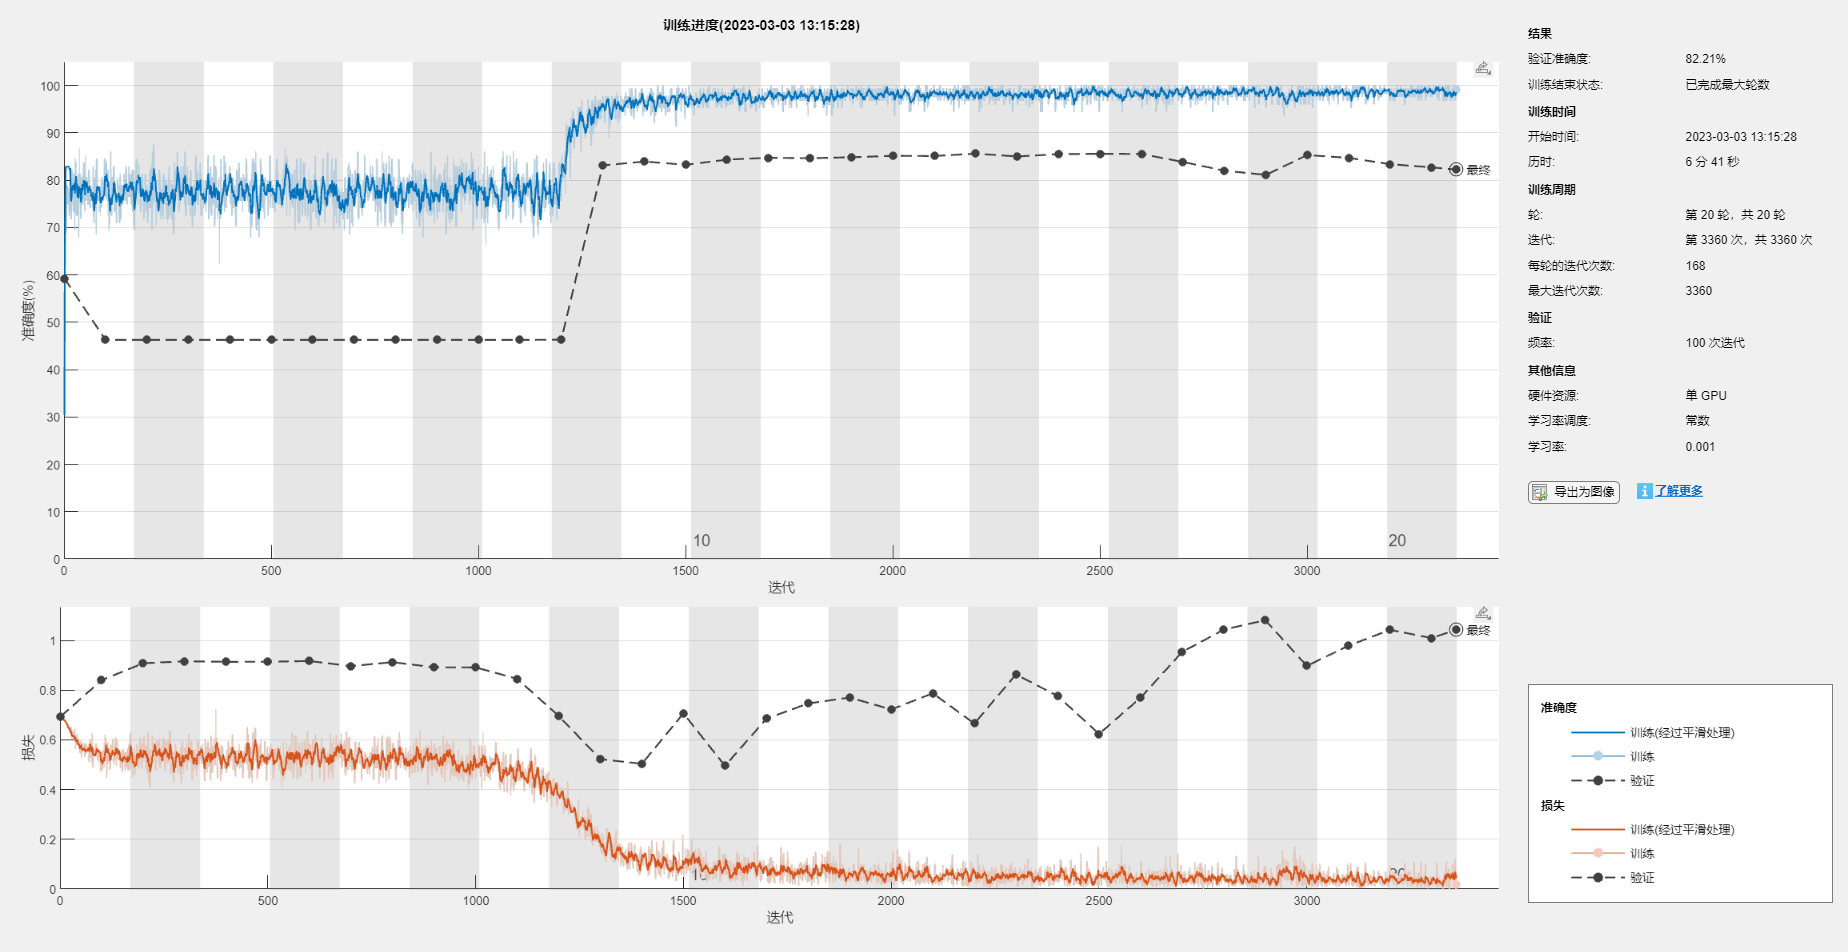

options = trainingOptions('sgdm',...
'ExecutionEnvironment','gpu',...
'InitialLearnRate',0.001,...
'MiniBatchSize',128,...
'MaxEpochs',20,...
'Shuffle','every-epoch',...
'ValidationData',{valImgs,vallabels},...
'ValidationFrequency',100,...
'Verbose',true,...
'Plots','training-progress');
net = trainNetwork(trainImgs,trainlabels,lgraph,options);

## 验证集验证

%计算识别准确率
pred_vallabels = classify(net,valImgs);
test_Acc = sum(pred_vallabels == vallabels)/numel(vallabels)

test_Acc = 0.8221

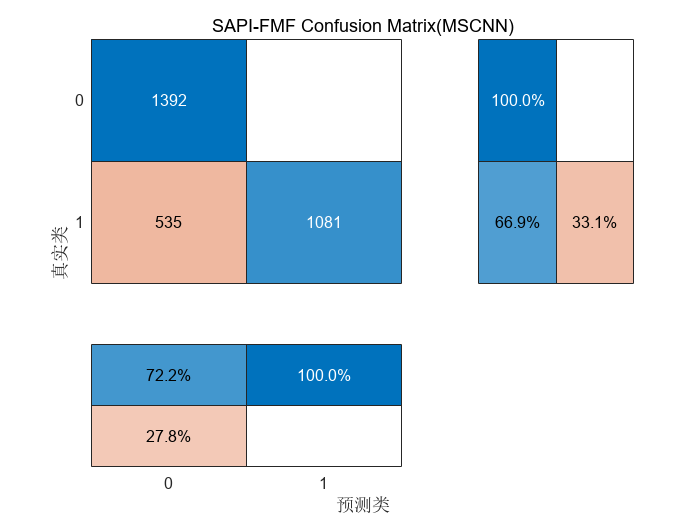

%绘制混淆矩阵
cm = confusionchart(vallabels,pred_vallabels); %推荐使用
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'SAPI-FMF Confusion Matrix';
cm.RowSummary = 'row-normalized';
cm.Title = 'SAPI-FMF Confusion Matrix(MSCNN)'; 

## 测试集验证

load('C:\Users\Administrator\Documents\MATLAB\SAPI-FMF\SAPI-FMF 数据集\最终测试集_不带标签\testdata5.mat')
test_img1 = video;
pred_labels1 = classify(net,test_img1);

load('C:\Users\Administrator\Documents\MATLAB\SAPI-FMF\SAPI-FMF 数据集\最终测试集_不带标签\testdata6.mat')
test_img2 = video;
pred_labels2 = classify(net,test_img2);

load('C:\Users\Administrator\Documents\MATLAB\SAPI-FMF\SAPI-FMF 数据集\最终测试集_不带标签\testdata7.mat')
test_img3 = video;
pred_labels3 = classify(net,test_img3);

load('C:\Users\Administrator\Documents\MATLAB\SAPI-FMF\SAPI-FMF 数据集\最终测试集_不带标签\testdata8.mat')
test_img4 = video;
pred_labels4 = classify(net,test_img4);


## 对比试验（简单卷积神经网络）

正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　７６．５６％　｜　　４６．２８％　｜　　１．４０６９　｜　２．３５７６　｜　　０．００１０　｜
｜　　　１　｜　　　５０　｜　　　　　００：００：０１　｜　　　９４．５３％　｜　　　　　　　　　｜　　０．１２１５　｜　　　　　　　　｜　　０．００１０　｜
｜　　　１　｜　　１００　｜　　　　　００：００：０２　｜　　　９７．６６％　｜　　８０．２９％　｜　　０．０５７１　｜　０．９３１８　｜　　０．００１０　｜
｜　　　１　｜　　１５０　｜　　　　　００：００：０３　｜　　　９７．６６％　｜　　　　　　　　　｜　　０．０３６４　｜　　　　　　　　｜　　０．００１０　｜
｜　　　２　｜　　２００　｜　　　　　００：００：０４　｜　　　９９．２２％　｜　　８０．５２％　｜　　０．０２５２　｜　１．１１５７　｜　　０．００１０　｜
｜　　　２　｜　　２５０　｜　　　　　００：００：０５　｜　　　９８．４４％　｜　　　　　　　　　｜　　０．０５５０　｜　　　　　　　　｜　　０．００１０　｜
｜　　　２　｜　　３００　｜　　　　　００：００：０６　｜　　　９８．４４％　｜　　７８．１９％　｜　　０．０３０２　｜　１．２０６４　｜　　０．００１０　｜
｜　　　３　｜　　３５０　｜　　　　　００：００：０７　｜　　　９８．４４％　｜　　　　　　　　　｜　　０．０３４１　｜　　　　　　　　｜　　０．００１０　｜
｜　　　３　｜　　４００　｜　　　　　００：００：０

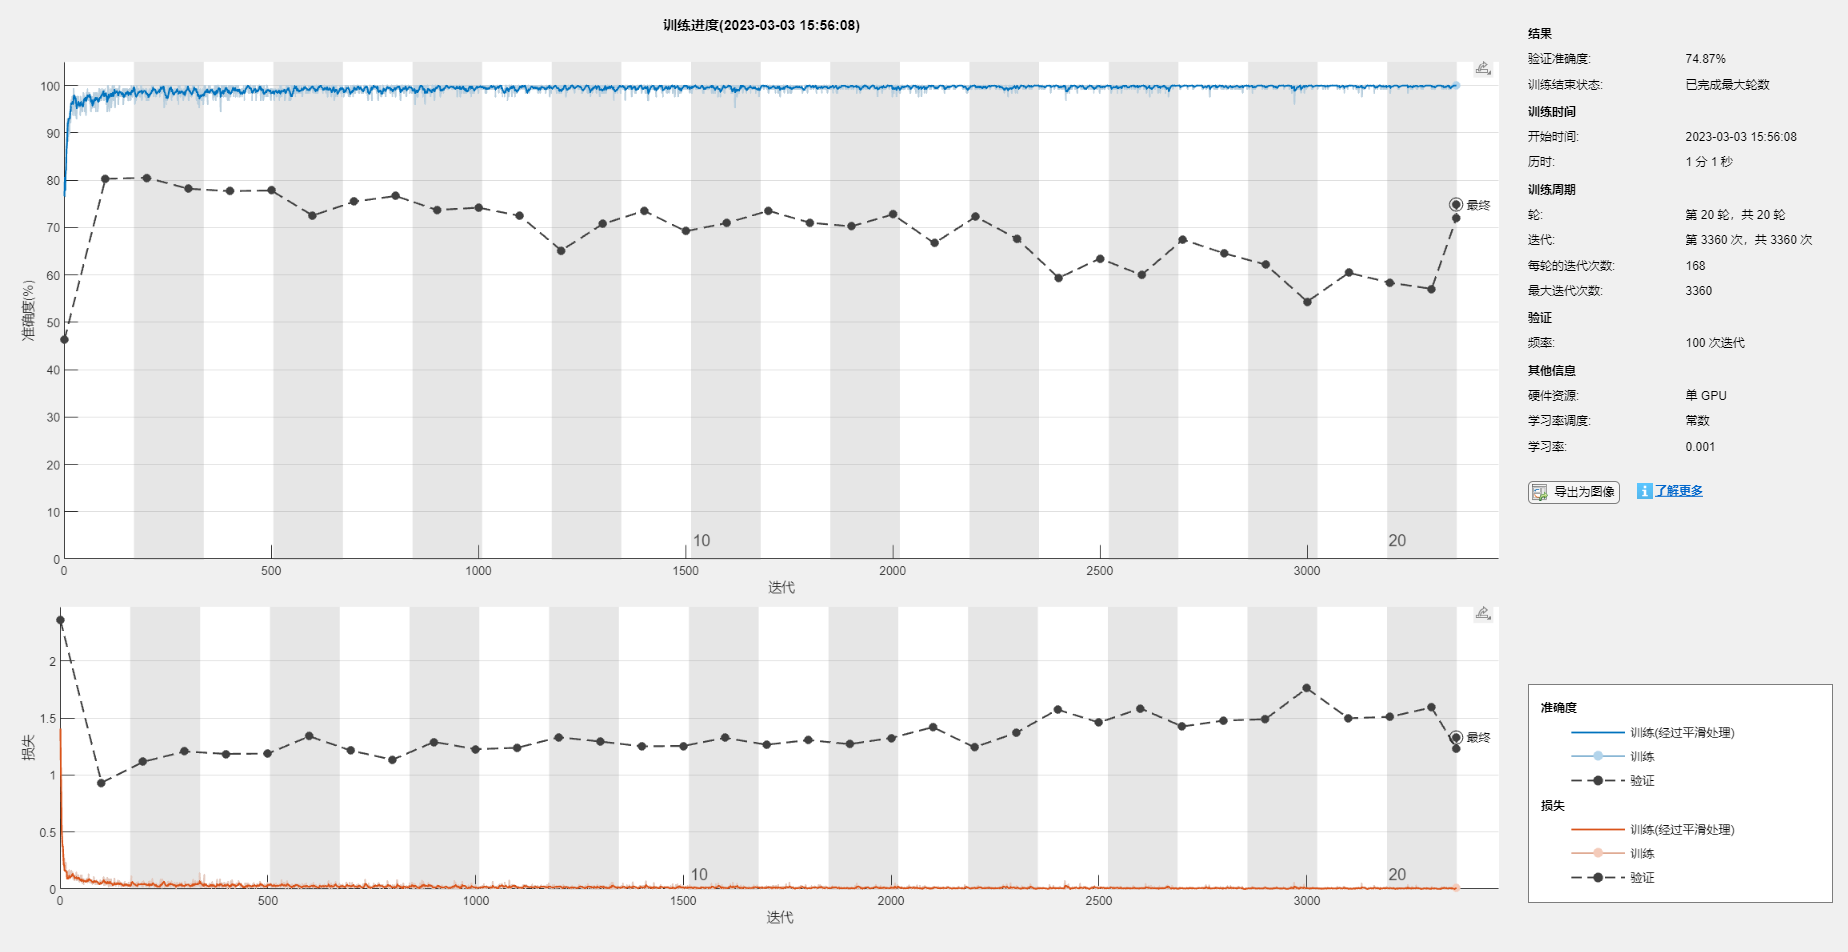

layers = [
    imageInputLayer([32,32,3],'Normalization','zerocenter')
    convolution2dLayer([5,5],32,"Padding",2)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(3,'Stride',2)
    convolution2dLayer([5,5],32,'Padding',2)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(3,'Stride',2)
    convolution2dLayer([5,5],64,"Padding",2)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(3,'Stride',2)
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer];

% 训练网络
options = trainingOptions('sgdm',...
'ExecutionEnvironment','gpu',...
'InitialLearnRate',0.001,...
'MiniBatchSize',128,...
'MaxEpochs',20,...
'Shuffle','every-epoch',...
'ValidationData',{valImgs,vallabels},...
'ValidationFrequency',100,...
'Verbose',true,...
'Plots','training-progress');
net1 = trainNetwork(trainImgs,trainlabels,layers,options);

net1.Layers

ans =   具有以下层的 18×1 Layer 数组:

     1   'imageinput'    图像输入      32×32×3 图像: 'zerocenter' 归一化
     2   'conv_1'        二维卷积      32 5×5×3 卷积: 步幅 [1  1]，填充 [2  2  2  2]
     3   'batchnorm_1'   批量归一化     批量归一化: 32 个通道
     4   'relu_1'        ReLU         ReLU
     5   'maxpool_1'     二维最大池化   3×3 最大池化: 步幅 [2  2]，填充 [0  0  0  0]
     6   'conv_2'        二维卷积      32 5×5×32 卷积: 步幅 [1  1]，填充 [2  2  2  2]
     7   'batchnorm_2'   批量归一化     批量归一化: 32 个通道
     8   'relu_2'        ReLU         ReLU
     9   'maxpool_2'     二维最大池化   3×3 最大池化: 步幅 [2  2]，填充 [0  0  0  0]
    10   'conv_3'        二维卷积      64 5×5×32 卷积: 步幅 [1  1]，填充 [2  2  2  2]
    11   'batchnorm_3'   批量归一化     批量归一化: 64 个通道
    12   'relu_3'        ReLU         ReLU
    13   'maxpool_3'     二维最大池化   3×3 最大池化: 步幅 [2  2]，填充 [0  0  0  0]
    14   'fc_1'          全连接        64 全连接层
    15   'relu_4'        ReLU         ReLU
    16   'fc_2'          全连接   

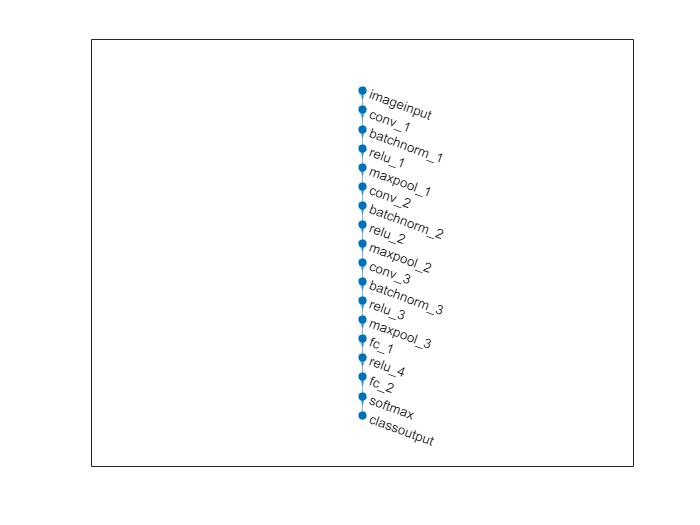


plot(net1)


%验证集验证
%计算识别准确率
pred_vallabels1 = classify(net1,valImgs);
test_Acc1 = sum(pred_vallabels1 == vallabels)/numel(vallabels)

test_Acc1 = 0.7487

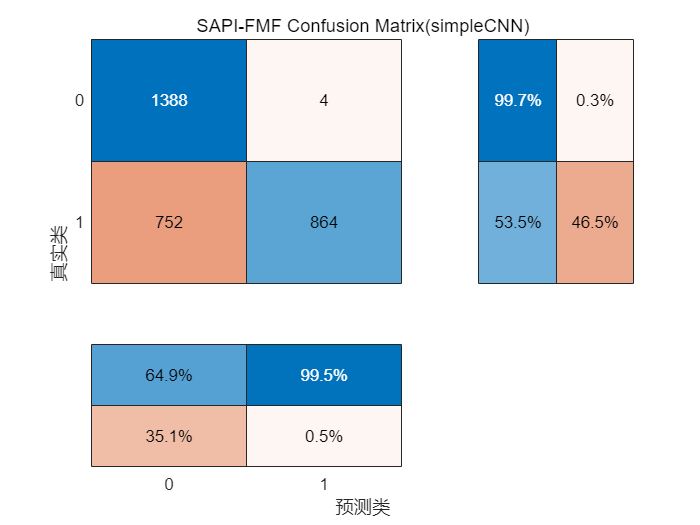

%绘制混淆矩阵
cm1 = confusionchart(vallabels,pred_vallabels1); %推荐使用
cm1.ColumnSummary = 'column-normalized';
cm1.RowSummary = 'row-normalized';
cm1.Title = 'SAPI-FMF Confusion Matrix';
cm1.RowSummary = 'row-normalized';
cm1.Title = 'SAPI-FMF Confusion Matrix(simpleCNN)'; 